# Diseño de un sistema de control con observador de estados de orden mínimo

#### El controlador-obervador está en el camino de retroalimentación 

% Ejemplo seccion 10-7 Texto Ogata. Diseño de sistemas de control con
% observadores
clear
close all
A = [0 1 0;0 0 1;0 -1 0]

A =      0     1     0
     0     0     1
     0    -1     0


B = [0;0;1]

B =      0
     0
     1


C=[1 0 0];
D=0;
J = [-1+1i -1-1i -8]

J =   -1.0000 + 1.0000i  -1.0000 - 1.0000i  -8.0000 + 0.0000i


K = acker(A,B,J)

K =     16    17    10


Aaa = 0

Aaa = 0

Aab = [1 0]

Aab =      1     0


Aba = [0;0]

Aba =      0
     0


Abb = [0 1;-1 0]

Abb =      0     1
    -1     0


Ba = 0

Ba = 0

Bb = [0;1]

Bb =      0
     1


L = [-4 -4]

L =     -4    -4


Ke = acker(Abb',Aab',L)'

Ke =      8
    15


% Obtención de la FT del controlador-observador y
% respuesta sistema de control con observador 
% Configuracion 2

## Obtención de la Función de Transferencia del Controlador-obervador

Ka=K(1);
Kb=K(2:3);
Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);
[num,den] = ss2tf(Atilde,Btilde,-Ctilde,-Dtilde)

num =   302.0000  303.0000  256.0000


den =      1    18   113


#### Función de transferencia del controlador-observador en lazo abierto

Gcobsol=tf(num,den)

Gcobsol =
 
  302 s^2 + 303 s + 256
  ---------------------
    s^2 + 18 s + 113
 
Continuous-time transfer function.
Model Properties


pole(Gcobsol)

ans =   -9.0000 + 5.6569i
  -9.0000 - 5.6569i


#### Función de transferencia de la planta

numol=[0 0 1];
denol=[1 0 1 0];
Gsol=tf(numol,denol)

Gsol =
 
     1
  -------
  s^3 + s
 
Continuous-time transfer function.
Model Properties


#### Función de transferencia del sistema de control con controlador-observador en lazo cerrado

%Gcsol=Gsol*Gcobsol;
% Gcsol=series(Gsol,Gcobsol)
% Funcion de transferencia del sistema de control con observador, en lazo
% cerrado
Gcscl=feedback(Gsol,Gcobsol)

Gcscl =
 
                 s^2 + 18 s + 113
  ----------------------------------------------
  s^5 + 18 s^4 + 114 s^3 + 320 s^2 + 416 s + 256
 
Continuous-time transfer function.
Model Properties


#### Respuesta del sistema de control con observador en lazo cerrado a una

#### entrada escalon unitaria  sin la ganancia N

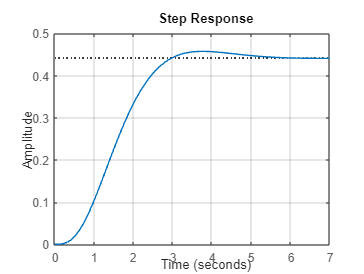

figure(1)
step(Gcscl)
grid

[y,t]=step(Gcscl);
S=stepinfo(y,t)

S = struct with fields:
         RiseTime: 1.7334
    TransientTime: 4.6746
     SettlingTime: 4.6746
      SettlingMin: 0.3986
      SettlingMax: 0.4573
        Overshoot: 3.5731
       Undershoot: 0
             Peak: 0.4573
         PeakTime: 3.7532


#### Respuesta del sistema de control con observador en lazo cerrado a una

#### entrada escalon unitaria  con la ganancia N

N=1/dcgain(Gcscl)

N = 2.2655

Gcscl1=N*Gcscl

Gcscl1 =
 
            2.265 s^2 + 40.78 s + 256
  ----------------------------------------------
  s^5 + 18 s^4 + 114 s^3 + 320 s^2 + 416 s + 256
 
Continuous-time transfer function.
Model Properties


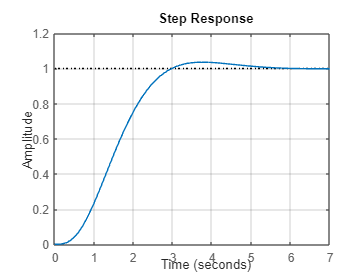

figure(2)
step(Gcscl1)
grid

[y,t]=step(Gcscl1);
S=stepinfo(y,t)

S = struct with fields:
         RiseTime: 1.7334
    TransientTime: 4.6746
     SettlingTime: 4.6746
      SettlingMin: 0.9031
      SettlingMax: 1.0359
        Overshoot: 3.5731
       Undershoot: 0
             Peak: 1.0359
         PeakTime: 3.7532


#### Obtención de la respuesta en lazo cerrado para el sistema sin observador

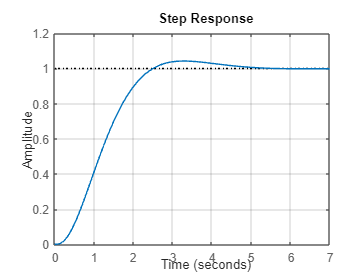

syscl=ss(A-B*K,B*K(1),C,D);
figure(4)
step(syscl)
grid

[y,t]=step(syscl);
S=stepinfo(y,t)

S = struct with fields:
         RiseTime: 1.5410
    TransientTime: 4.4176
     SettlingTime: 4.4176
      SettlingMin: 0.9041
      SettlingMax: 1.0424
        Overshoot: 4.4320
       Undershoot: 0
             Peak: 1.0424
         PeakTime: 3.2697


#### Diagrama de bode de la respuesta en lazo cerrado para el sistema controlador-observador 2

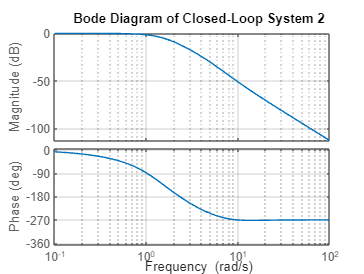

figure(5)
bode(Gcscl1,logspace(-1,2))
title('Bode Diagram of Closed-Loop System 2')
grid

#### Margen de fase del controlador-observador

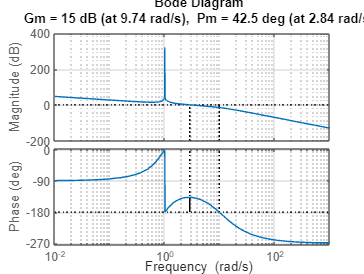

figure(6)
margin(Gsol*Gcobsol)
grid